# LearnFiltering

The purpose of this file is to provide a sandbox for scripting and testing filtering, postprocessing and basic classification for Gaze Data. Scripts included with this folder are to be shared/copied by participants of the Eye Tracking in VR workshop at VSS 2018.

addpath(genpath(pwd))
close all
clc

## Read table into memory

ExpData_raw = readtable('ExpData.csv');

## Identify missing/erroneous values

Interpolate for the following types of values: 1. NaN values. 2. Values outside FoV. 3. Values with incorrect Pupil sizes.

% Total number of samples
N = height(ExpData_raw);

% 1. Find all NaN values.
loc1 = logical(sum(isnan(ExpData_raw.Variables), 2));

% 2. Values outside FoV.
loc2 = ExpData_raw.POR_1 > 1080 | ExpData_raw.POR_2 > 1920 | ExpData_raw.POR_1 < 1 | ExpData_raw.POR_2 < 1;

% 3. Values with incorrect Pupil sizes.
loc3 = isoutlier(ExpData_raw.L_pd, 'movmedian', 5, 'ThresholdFactor', 2) | ...
        isoutlier(ExpData_raw.R_pd, 'movmedian', 5, 'ThresholdFactor', 2);

% Combine all potential locations to find a common mask.
loc = loc1 | loc2 | loc3;

fprintf('Atleast %f%% of points have an error condition\n', 100*sum(loc)/N)

Atleast 7.159104% of points have an error condition


## Observe Variable Sampling Rate

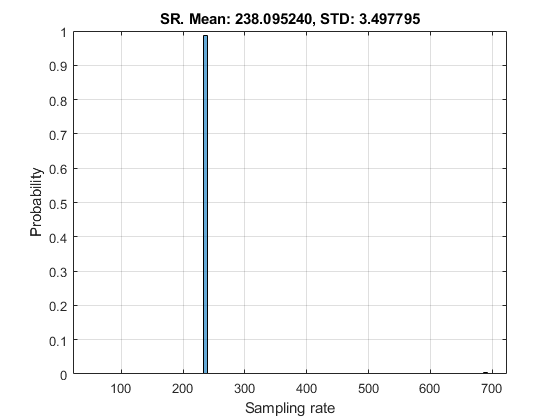

% Zero center the timing values in the raw data
ExpData_raw.T = ExpData_raw.T - ExpData_raw.T(1);
SRvals = 1./diff(ExpData_raw.T);

figure;
histogram(SRvals, 100, 'Normalization', 'probability')
xlabel('Sampling rate'); ylabel('Probability');
grid on;
title(sprintf('SR. Mean: %f, STD: %f', 1/median(diff(ExpData_raw.T)), mad(1./diff(ExpData_raw.T))))

## Generate a new, well spaced time signal

disp('Proceeding to reinterpolate to new Sampling Rate.')

Proceeding to reinterpolate to new Sampling Rate.


SR_desired = input('Enter desired SR: ');

## Create ordered time stamps

DurationOfData = (ExpData_raw.T(end) - ExpData_raw.T(1));
newT = linspace(ExpData_raw.T(1), ExpData_raw.T(end), round(DurationOfData*SR_desired));
fprintf('The new Sampling Rate is Mean: %f, STD: %f.\n', 1/mean(diff(newT)), std(1./diff(newT)))

The new Sampling Rate is Mean: 249.991213, STD: 0.000000.


## Interpolate over "bad" locations and convert to a new clean time stamp

It is essential to keep the timing difference between every sample as fixed. 

ExpData.T = newT;

L_gv_1 = interp1(ExpData_raw.T(~loc), ExpData_raw.L_gv_1(~loc), newT, 'spline', 'extrap');
L_gv_2 = interp1(ExpData_raw.T(~loc), ExpData_raw.L_gv_2(~loc), newT, 'spline', 'extrap');
L_gv_3 = interp1(ExpData_raw.T(~loc), ExpData_raw.L_gv_3(~loc), newT, 'spline', 'extrap');
ExpData.L_gv = normr([L_gv_1(:), L_gv_2(:), L_gv_3(:)]);
ExpData.L_pd = interp1(ExpData_raw.T(~loc), ExpData_raw.L_pd(~loc), newT, 'spline', 'extrap');

R_gv_1 = interp1(ExpData_raw.T(~loc), ExpData_raw.R_gv_1(~loc), newT, 'spline', 'extrap');
R_gv_2 = interp1(ExpData_raw.T(~loc), ExpData_raw.R_gv_2(~loc), newT, 'spline', 'extrap');
R_gv_3 = interp1(ExpData_raw.T(~loc), ExpData_raw.R_gv_3(~loc), newT, 'spline', 'extrap');
ExpData.R_gv = normr([R_gv_1(:), R_gv_2(:), R_gv_3(:)]);
ExpData.R_pd = interp1(ExpData_raw.T(~loc), ExpData_raw.R_pd(~loc), newT, 'spline', 'extrap');

ExpData.POR_1 = interp1(ExpData_raw.T(~loc), ExpData_raw.POR_1(~loc), newT, 'spline', 'extrap');
ExpData.POR_2 = interp1(ExpData_raw.T(~loc), ExpData_raw.POR_2(~loc), newT, 'spline', 'extrap');

ExpData.Confidence = interp1(ExpData_raw.T, ExpData_raw.Confidence, newT, 'spline', 'extrap');
ExpData.Eye0_fr = interp1(ExpData_raw.T, ExpData_raw.Eye0_fr, newT, 'nearest', 'extrap');
ExpData.Eye1_fr = interp1(ExpData_raw.T, ExpData_raw.Eye1_fr, newT, 'nearest', 'extrap');
ExpData.Scene_fr = interp1(ExpData_raw.T, ExpData_raw.Scene_fr, newT, 'nearest', 'extrap');

% Compute raw Cyclopean GIW vector
ExpData.C_gv_raw = normr(ExpData.R_gv + ExpData.L_gv);

## Convert and filter Left Gaze vectors to Azimuth and Elevation signals

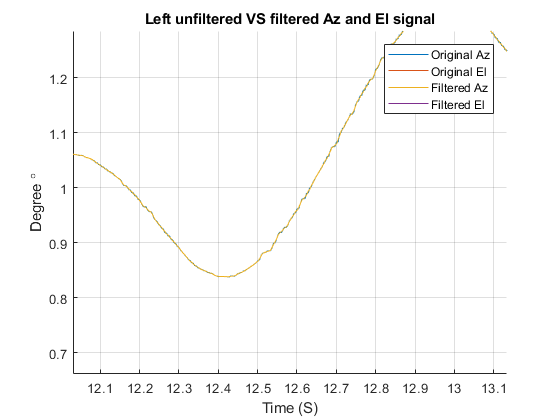

[ExpData.L_Az, ExpData.L_El, r] = cart2sph(-ExpData.L_gv(:, 1), ExpData.L_gv(:, 3), ExpData.L_gv(:, 2));

% Plot unfiltered
figure; hold on;
plot(ExpData.T, ExpData.L_Az); plot(ExpData.T, ExpData.L_El);

% Remove outliers using median filtering. Hint: Check out MATLAB's function
% doc isoutlier
ExpData.L_Az = medfilt1(ExpData.L_Az); ExpData.L_El = medfilt1(ExpData.L_El);

% Apply S-G filter
% Refer to lecture notes on the ideal parameters for S-G filtering. If the
% fitting degree parameter is very high, the polynomial fit will tend overfit to
% the local distribution of data points. Low fitting degree value may tend
% to underfit the data. For our application, 2 to 3 degrees should be fine.

ExpData.L_Az = smooth(ExpData.L_Az, 5, 'sgolay', 3); 
ExpData.L_El = smooth(ExpData.L_El, 5, 'sgolay', 3);

% Plot filtered
plot(ExpData.T, ExpData.L_Az); plot(ExpData.T, ExpData.L_El);
hold off;
grid on;
xlabel('Time (S)'); ylabel('Degree \circ')
legend('Original Az', 'Original El', 'Filtered Az', 'Filtered El')
title('Left unfiltered VS filtered Az and El signal')


% Convert back from spherical to cartesian coordinates
[ExpData.L_gv(:, 1), ExpData.L_gv(:, 3), ExpData.L_gv(:, 2)] = sph2cart(ExpData.L_Az, ExpData.L_El, r);
ExpData.L_gv(:, 1) = -ExpData.L_gv(:, 1);

## Convert and filter Right Gaze vectors to Azimuth and Elevation signals

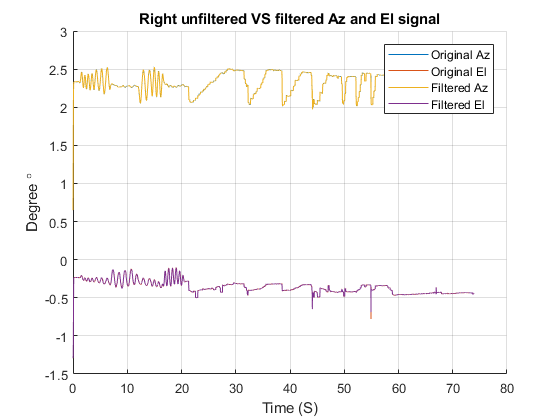

[ExpData.R_Az, ExpData.R_El, r] = cart2sph(-ExpData.R_gv(:, 1), ExpData.R_gv(:, 3), ExpData.R_gv(:, 2));

% Plot unfiltered
figure; hold on;
plot(ExpData.T, ExpData.R_Az); plot(ExpData.T, ExpData.R_El);

% Remove outliers
ExpData.R_Az = medfilt1(ExpData.R_Az); ExpData.R_El = medfilt1(ExpData.R_El);

% Apply S-G filter
ExpData.R_Az = smooth(ExpData.R_Az, 5, 'sgolay', 3); 
ExpData.R_El = smooth(ExpData.R_El, 5, 'sgolay', 3);

% Plot filtered
plot(ExpData.T, ExpData.R_Az); plot(ExpData.T, ExpData.R_El);
hold off; 
grid on
xlabel('Time (S)'); ylabel('Degree \circ')
legend('Original Az', 'Original El', 'Filtered Az', 'Filtered El')
title('Right unfiltered VS filtered Az and El signal')


% Convert back from spherical to cartesian coordinates
[ExpData.R_gv(:, 1), ExpData.R_gv(:, 3), ExpData.R_gv(:, 2)] = sph2cart(ExpData.R_Az, ExpData.R_El, r);
ExpData.R_gv(:, 1) = -ExpData.R_gv(:, 1);

## Calculate Gaze Velocity

Since the Left and Right Gaze vectors have their the origins on a line L, the Cyclopean Gaze vector can be seen as a vector emerging from the center of the line L. Hence, Cyclopean Gaze vector is simply a vector addition of the Left and Right Gaze vector components.

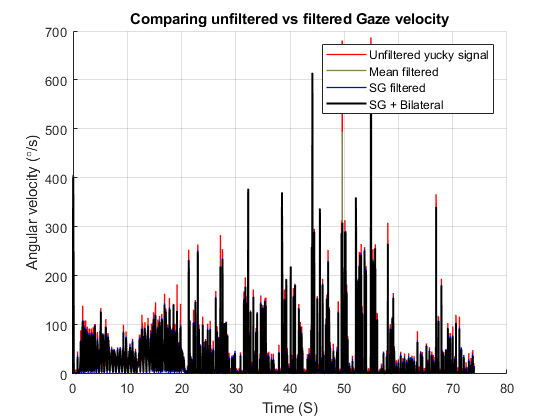

ExpData.C_gv = normr(ExpData.L_gv + ExpData.R_gv);
ExpData.EIH_Vel = findGazeVelocity(ExpData.T, ExpData.C_gv, 1, 0);
EIH_Vel_Meanfiltered = findGazeVelocity(ExpData.T, ExpData.C_gv_raw, 2, 0);
EIH_Vel_SGfiltered = findGazeVelocity(ExpData.T, ExpData.C_gv, 0, 0);
EIH_Vel_unfiltered_raw = findGazeVelocity(ExpData.T, ExpData.C_gv_raw, 0, 0);


figure;
hold on
plot(ExpData.T, EIH_Vel_unfiltered_raw, 'LineWidth', 1., 'Color', [1,0,0])
plot(ExpData.T, EIH_Vel_Meanfiltered, 'LineWidth', 1., 'Color', [0.5,0.5,0.3])
plot(ExpData.T, EIH_Vel_SGfiltered, 'LineWidth', 1., 'Color', [0,0,1])
plot(ExpData.T, ExpData.EIH_Vel, 'LineWidth', 1.5, 'Color', [0,0,0])
xlabel('Time (S)'); ylabel('Angular velocity (\circ/s)')
grid on;
title('Comparing unfiltered vs filtered Gaze velocity')
legend('Unfiltered yucky signal', 'Mean filtered', 'SG filtered', 'SG + Bilateral')

## Calculate Gaze Acceleration

ExpData.EIH_Acc = [diff(ExpData.EIH_Vel(:))./diff(ExpData.T(:)); 0];

save(fullfile('WorkshopData', 'FilteredData.mat'), 'ExpData')